clc
clear

kNN = readtable("results\Performance\testing\kNN_performance.csv");
kNN2 = readtable("results\Performance\testing\kNN2_performance.csv");
kNN4 = readtable("results\Performance\testing\kNN4_performance.csv");
LDA2 = readtable("results\Performance\testing\LDA2_performance.csv");
LDA4 = readtable("results\Performance\testing\LDA4_performance.csv");
SVM_G = readtable("results\Performance\testing\SVM_G_performance.csv");

threshold = linspace(0,1,200);

## Plot results

### Plot colours

% Plot colours
orange = '#FF9A5B';
blue   = '#06ACE9';
purple = '#7E2F8E';
green = '#77AC30';
cyan = '#4DBEEE';
maroon = '#A2142F';
black = '#000000';

### Plot style

% Plot style
line_width = 0.7;

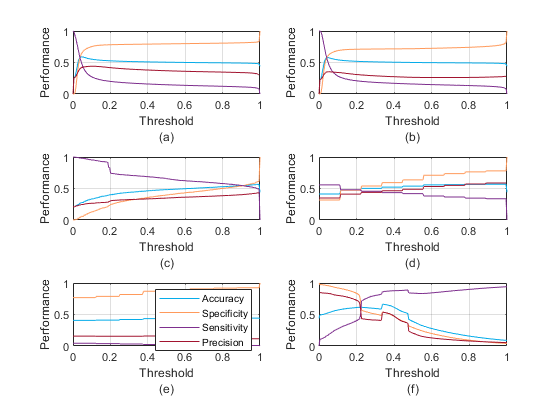

% Plot each model separately 

figure();

subplot(3,2,6)
plot(threshold, SVM_G.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, SVM_G.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, SVM_G.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, SVM_G.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold')
xlabel(["Threshold", "(f)"])
ylabel('Performance')
% legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
% print('results/Performance/testing/useful/SVM_G_Performance', '-dpng', '-r600')

subplot(3,2,5)
plot(threshold, kNN.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold", "(e)"])
ylabel('Performance');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision', 'Location', 'SouthEast');
grid on;
hold off;
% print('results/Performance/testing/useful/kNN_Performance', '-dpng', '-r600')

subplot(3,2,3)
plot(threshold, kNN2.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN2.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN2.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold", "(c)"])
ylabel('Performance');
% legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
% print('results/Performance/testing/useful/kNN2_Performance', '-dpng', '-r600')

subplot(3,2,4)
plot(threshold, kNN4.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN4.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN4.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold", "(d)"])
ylabel('Performance');
% legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
% print('results/Performance/testing/useful/kNN4_Performance', '-dpng', '-r600')

subplot(3,2,1)
plot(threshold, LDA2.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, LDA2.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, LDA2.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold", "(a)"])
ylabel('Performance');
% legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
% print('results/Performance/testing/useful/LDA2_Performance', '-dpng', '-r600')

subplot(3,2,2)
plot(threshold, LDA4.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, LDA4.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, LDA4.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA4.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold", "(b)"])
ylabel('Performance');
% legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;

% print('results/Performance/testing/useful/LDA4_Performance', '-dpng', '-r600')


print('results/Performance/testing/useful/All_models_Performance', '-dpng', '-r600')

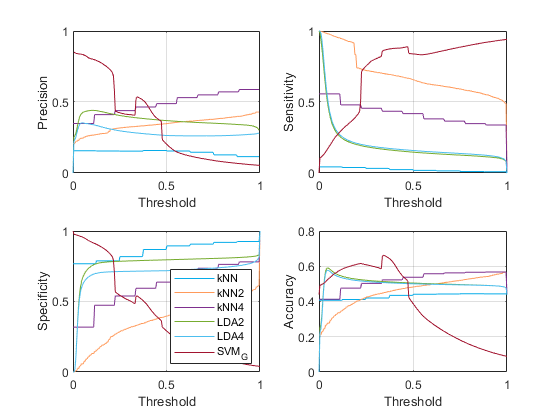

% Plot individual Parameters
figure();

subplot(2,2,1);
plot(threshold, kNN.precision, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.precision, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.precision, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.precision, '-', 'LineWidth', line_width, 'Color', green);
plot(threshold, LDA4.precision, '-', 'LineWidth', line_width, 'Color', cyan);
plot(threshold, SVM_G.precision, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold"]);
ylabel('Precision');
% legend('kNN', 'kNN2', 'kNN4', 'LDA2', 'LDA4', 'SVM_G');
grid on;
hold off;
% print('results/Performance/testing/useful/precision_Performance', '-dpng', '-r600')

subplot(2,2,2);
plot(threshold, kNN.sensitivity, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.sensitivity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.sensitivity, '-', 'LineWidth', line_width, 'Color', green);
plot(threshold, LDA4.sensitivity, '-', 'LineWidth', line_width, 'Color', cyan);
plot(threshold, SVM_G.sensitivity, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold"]);
ylabel('Sensitivity');
% legend('kNN', 'kNN2', 'kNN4', 'LDA2', 'LDA4', 'SVM_G');
grid on;
hold off;
% print('results/Performance/testing/useful/sensitivity_Performance', '-dpng', '-r600')

subplot(2,2,3);
plot(threshold, kNN.specificity, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.specificity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.specificity, '-', 'LineWidth', line_width, 'Color', green);
plot(threshold, LDA4.specificity, '-', 'LineWidth', line_width, 'Color', cyan);
plot(threshold, SVM_G.specificity, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel(["Threshold"]);
ylabel('Specificity');
legend('kNN', 'kNN2', 'kNN4', 'LDA2', 'LDA4', 'SVM_G', 'Location', 'SouthEast');
grid on;
hold off;
% print('results/Performance/testing/useful/specificity_Performance', '-dpng', '-r600')

subplot(2,2,4);
plot(threshold, kNN.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.accuracy, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.accuracy, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.accuracy, '-', 'LineWidth', line_width, 'Color', green);
plot(threshold, LDA4.accuracy, '-', 'LineWidth', line_width, 'Color', cyan);
plot(threshold, SVM_G.accuracy, '-', 'LineWidth', line_width, 'Color', maroon);
% xlabel('Threshold');
xlabel("Threshold");
ylabel('Accuracy');
% legend('kNN', 'kNN2', 'kNN4', 'LDA2', 'LDA4', 'SVM_G');
grid on;
hold off;

% print('results/Performance/testing/useful/accuracy_Performance', '-dpng', '-r600')


print('results/Performance/testing/useful/All_metrics_Performance', '-dpng', '-r600')